# Error with respect to lambda and distortion magnitude

## Load and initiate

ella = [0.057:0.001:0.059 0.06:0.005:0.095 0.1:0.01:0.3];
maglist = 0:0.01:10;

sella = length(ella);
smaglist = length(maglist);

[x, y] = meshgrid(ella,maglist);

confidence_level = 0.9999999;
zscore = zscorer(confidence_level);

meanErrs = zeros(6,smaglist,sella);
stdErrs = zeros(6,smaglist,sella);
pixprop = zeros(1,sella);

names = ["drift x", "drift y", "hysteresis x", "hysteresis y", "creep x", "creep y"];

idx = 1;
for ell = ella
    load("lambda_" + ell + ".mat");
    meanErrs(:,:,idx) = S.meanErr;
    stdErrs(:,:,idx) = S.stdErr;
    pixprop(idx) = S.pixprop;
    idx = idx + 1;
end

x = x(2:end,:);
y = y(2:end,:);

## Plot

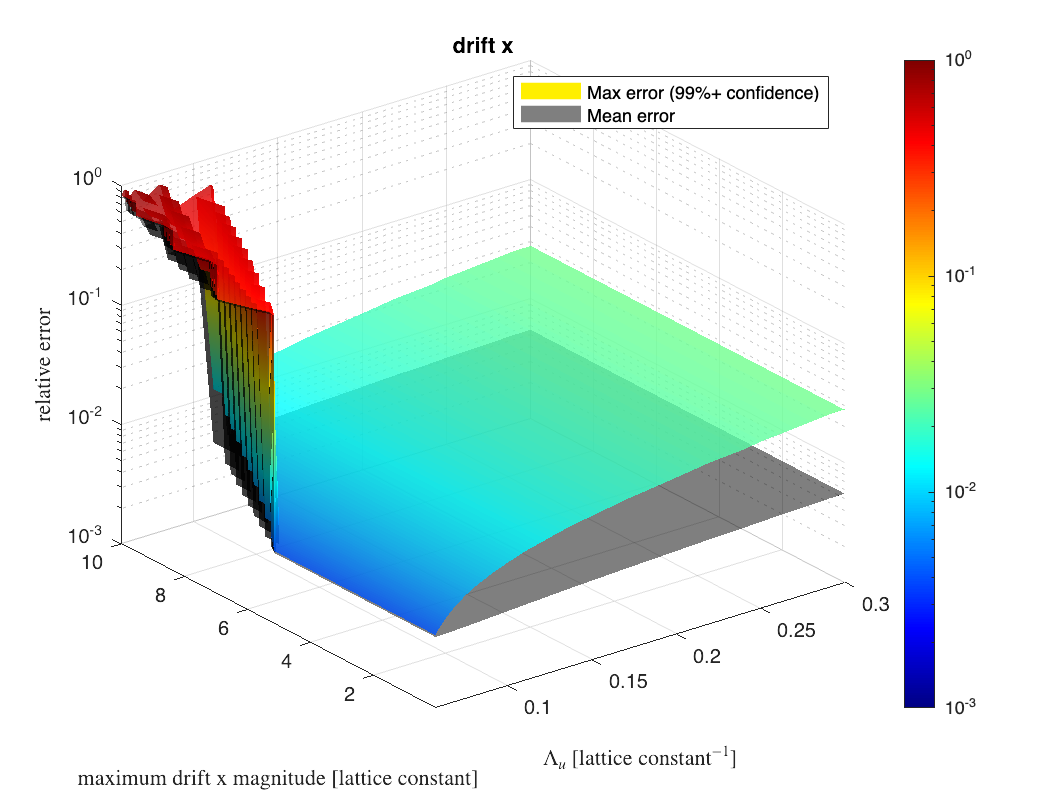

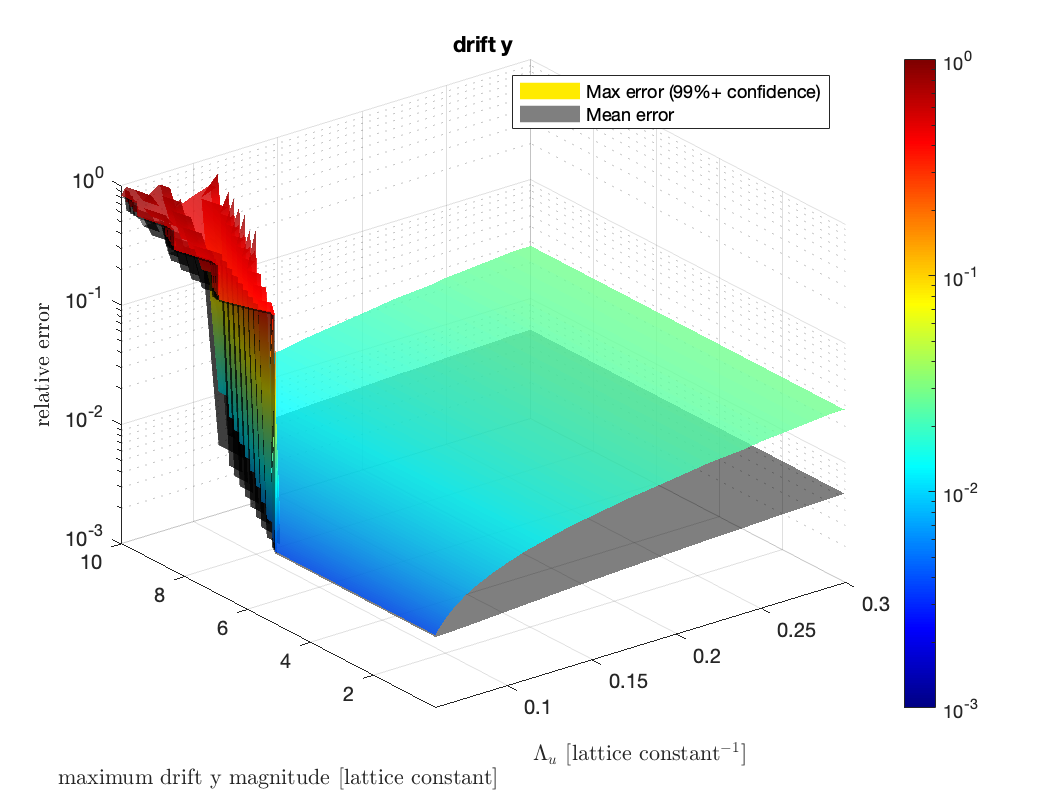

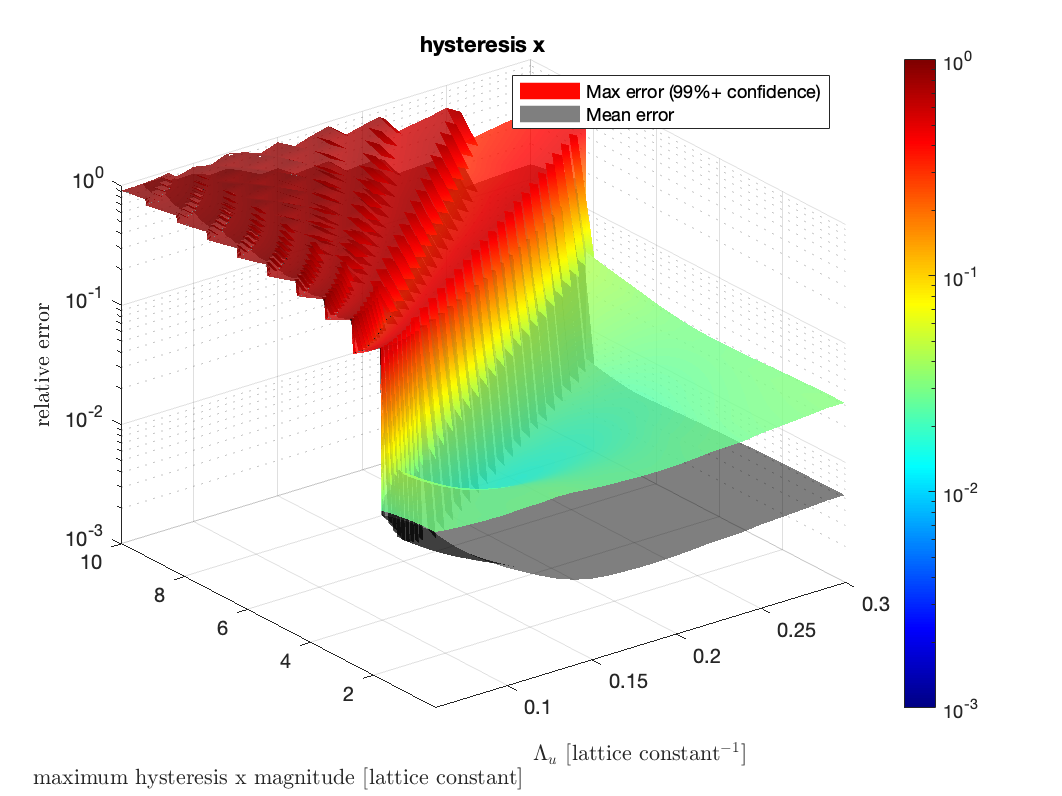

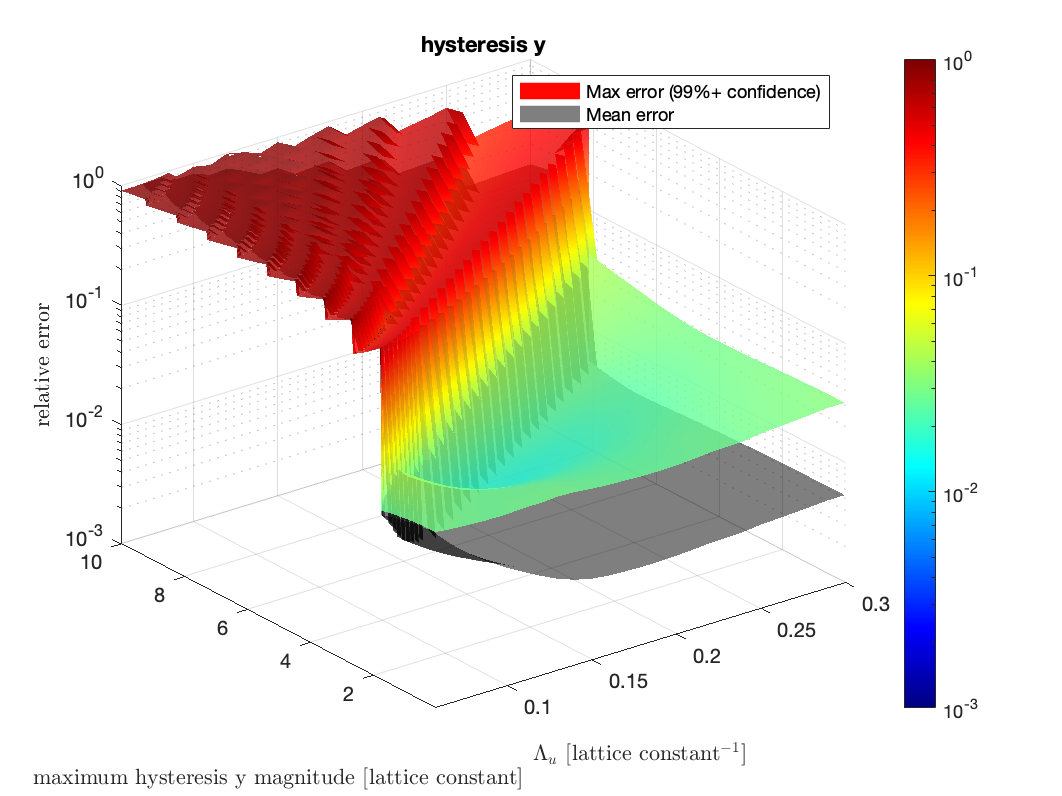

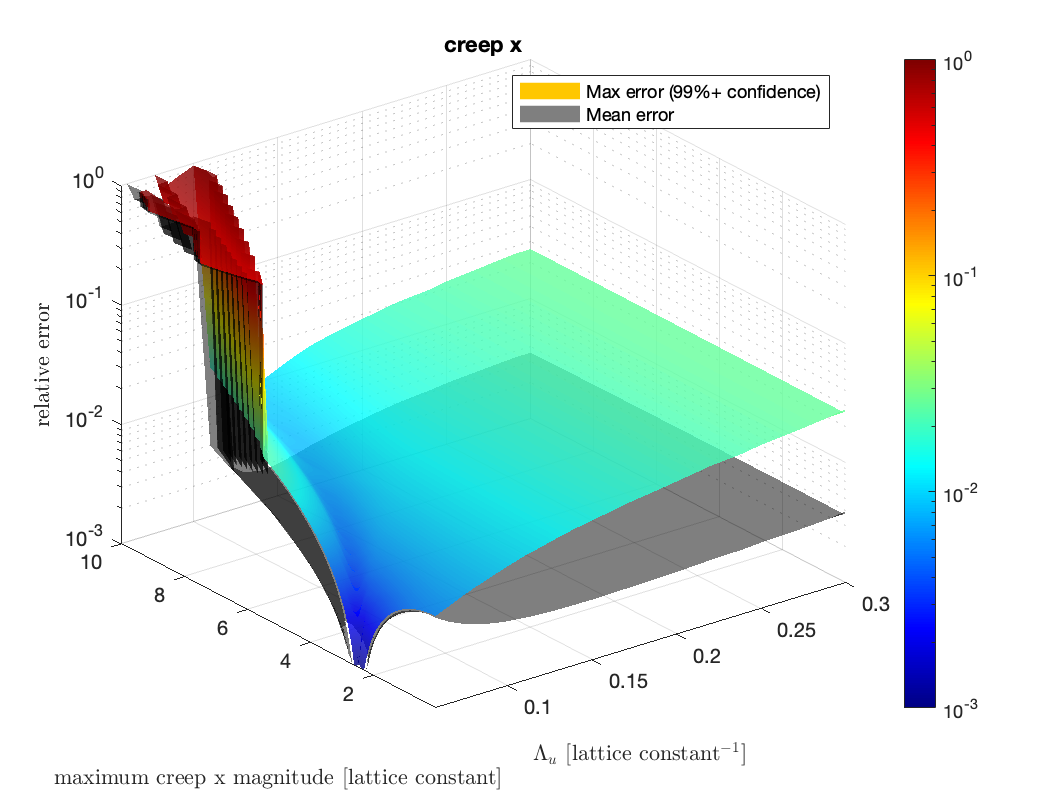

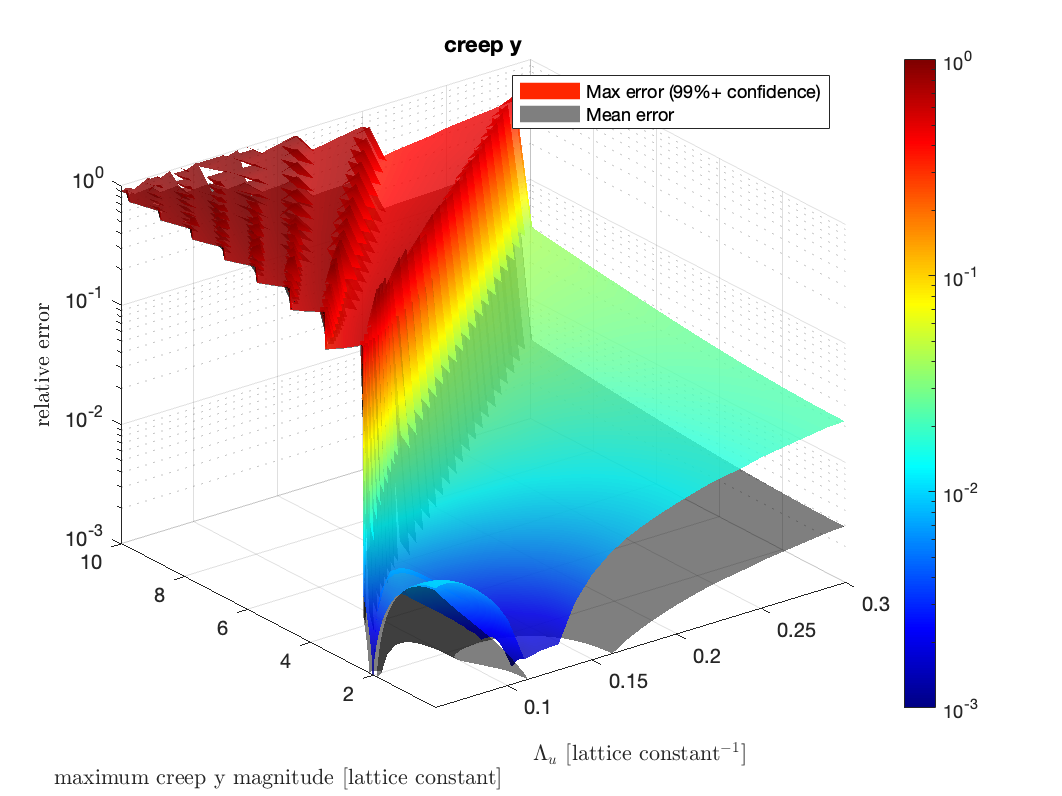

for ctr = 1:6
    figure;
    means = squeeze(meanErrs(ctr,2:end,:));
    stds = squeeze(stdErrs(ctr,2:end,:));
    surf(x,y,means+stds*zscore,"FaceAlpha",0.8);
    hold on
%     surf(x,y,means-zscore*stds,'FaceAlpha',0.2);
    colormap(jet);
    xlabel("$\Lambda_u$ [lattice constant$^{-1}$]","Interpreter","latex");
    ylabel("maximum " + names(ctr) + " magnitude [lattice constant]","Interpreter","latex");
    zlabel("relative error","Interpreter","latex");
    shading interp
    axis tight
    set(gca,'zscale','log');
    set(gca, "ColorScale","log");
    zlim([0.001 1])
    surf(x,y,means,'edgecolor','none','FaceColor','k','FaceAlpha',0.5);
%     clim([min(means(:)) max(means(:))]);
    colorbar;
    clim([0.001 1])
    legend('Max error (99%+ confidence)','Mean error','Location','northeast');
    title(names(ctr));
    hold off
%     saveas(gcf,"lambda vs noise " + names(ctr) + ".fig");
end